## get the data set

% this section for organizing ABGO data was made by Jonathan Calderon Chavez
% This is where you put the location of the directory
fileName = '/home/saturn/ABG/ABG_classification/data/pngs'; % Change this later on 

% This holds all the pngs, have not been split
rawData = imageDatastore(fileName, 'IncludeSubfolders',true, "LabelSource","foldernames"); 

## Making the test data

% [trainData, testData] = splitEachLabel(rawData,0.7,'randomized');
% trainLabels = trainData.Labels;
% testLabels = testData.Labels;

% This will create  a randomly sampled test group, remaining png are strored 
% rp contains all classes
[testIMDS, remainingPNGs] = splitEachLabel(rawData, 50, 'randomized'); 

## Making the validation data

% We extract the 50 OTHER pngs from the remaining PNGS at random 
% Note that the Include state makes remaining contain only other
[valP1IMDS, remainingOTHER] = splitEachLabel(remainingPNGs, 50, 'randomized', 'Include', 'other');

% We extract 200 pngs from the classes ABG 
% rp contains only abg
[valP2IMDS, remainingABG] = splitEachLabel(remainingPNGs, 200, 'randomized', "Exclude",'other');

% We will now combine the two halfs into one validation data store
validationIMDS = imageDatastore(cat(1,valP1IMDS.Files,valP2IMDS.Files));
validationIMDS.Labels = cat(1,valP1IMDS.Labels,valP2IMDS.Labels);

## Make Traning Data

% all the remaining png must go into training
% let combine the remaining other and ABG from earlier  
trainingIMDS = imageDatastore(cat(1, remainingABG.Files, remainingOTHER.Files)); 
trainingIMDS.Labels = cat(1, remainingABG.Labels, remainingOTHER.Labels);

% This are the important datastores
trainingIMDS;
validationIMDS;
testIMDS;

## Resize the data

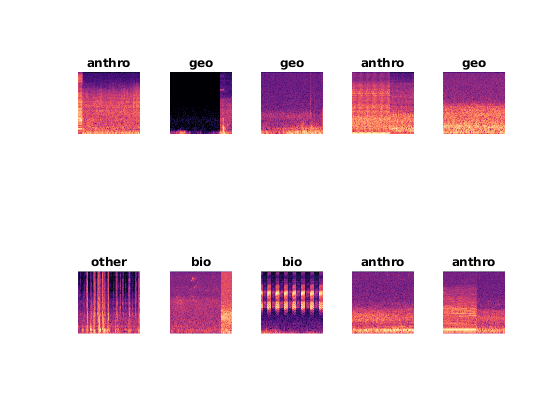

%resize datastore to [224, 224, 3]
train_audIMDS = augmentedImageDatastore([224, 224, 3], trainingIMDS);
validation_audIMDS = augmentedImageDatastore([224, 224, 3], validationIMDS);
test_audIMDS = augmentedImageDatastore([224, 224, 3], testIMDS);

% Important datastores have been resized to fit specified for
% the model
train_audIMDS;
validation_audIMDS;
test_audIMDS;
% end of data split

% View subset of images with labels
figure
numImages = numel(rawData.Labels);
perm = randperm(numImages,10);
for i = 1:10
    subplot(2,5,i);
    imshow(rawData.Files{perm(i)});
    title(rawData.Labels(perm(i)));
    drawnow;
end
hold off;

## Configure MobileNetv2 for ABG Data

% Mobilenetv2
lgraph = mobilenetv2("Weights","none");

% New layers to replace layers in mobilenetv2
% inputlayer = imageInputLayer([432 432 3],'Name','input');
fcLayer = fullyConnectedLayer(4,'Name','fc_layer');
smLayer = softmaxLayer('Name','sm_layer');
classLayer = classificationLayer('Name','output');

% lgraph = removeLayers(lgraph,'input_1');
lgraph = removeLayers(lgraph,'Logits');
lgraph = removeLayers(lgraph,'Logits_softmax');
lgraph = removeLayers(lgraph,'ClassificationLayer_Logits');

% lgraph = addLayers(lgraph,inputlayer);
lgraph = addLayers(lgraph,classLayer);
lgraph = addLayers(lgraph,fcLayer);
lgraph = addLayers(lgraph,smLayer);

% lgraph = connectLayers(lgraph,'input','Conv1');
lgraph = connectLayers(lgraph,'global_average_pooling2d_1','fc_layer');
lgraph = connectLayers(lgraph,'fc_layer','sm_layer');
lgraph = connectLayers(lgraph,'sm_layer','output');


%analyzeNetwork(lgraph);

% layers = [
%     imageInputLayer([432 432 3])
%     
%     convolution2dLayer([6 3],32,'Padding','same')
%     batchNormalizationLayer
%     reluLayer   
%     
%     maxPooling2dLayer(2,'Stride',2)
%     
%     convolution2dLayer([3 6],32,'Padding','same')
%     batchNormalizationLayer
%     reluLayer   
%     
%     maxPooling2dLayer(2,'Stride',2)
%     
%     convolution2dLayer(3,64,'Padding','same')
%     batchNormalizationLayer
%     reluLayer   
%     
%     convolution2dLayer(3,96,'Padding','same')
%     batchNormalizationLayer
%     reluLayer 
%     
%     convolution2dLayer(1,96,'Padding','same')
%     batchNormalizationLayer
%     reluLayer 
%     
%     maxPooling2dLayer(3,'Stride',2)
%     
%     fullyConnectedLayer(4)
%     softmaxLayer
%     classificationLayer];
% 
% analyzeNetwork(layers)
% 
% options0 = trainingOptions('sgdm', ...
%     'MaxEpochs',5, ...
%     'Momentum',0.8, ...
%     'MiniBatchSize',30, ...
%     'InitialLearnRate',0.5, ...
%     'ValidationData',validationIMDS, ...
%     'ValidationFrequency',30, ...
%     'Verbose',false, ...
%     'Plots','training-progress');
% 
% net0 = trainNetwork(trainingIMDS,layers,options0);
% 
% 
% YPred = classify(net0,testIMDS);
% accuracy0 = mean(YPred == testIMDS.Labels)

## Training Options 

options = trainingOptions('sgdm', ...
    'Momentum',0.7, ...
    'MiniBatchSize',40, ...
    'MaxEpochs',6,...
    'InitialLearnRate',0.06, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.9, ...
    'LearnRateDropPeriod',3, ...
    'ValidationData',validation_audIMDS, ...
    'ValidationFrequency',50, ...
    'Verbose',true, ...
    'DispatchInBackground',true, ...
    'Plots','training-progress');

net = trainNetwork(train_audIMDS,lgraph,options);

Training on single GPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:19 |       20.00% |       30.00% |       1.4955 |       7.9155 |          0.6000 |


|       1 |          50 |       00:01:49 |       40.00% |       31.38% |       1.3762 |       1.3353 |          0.6000 |


|       1 |         100 |       00:03:22 |       27.50% |       31.54% |       1.3354 |       1.3513 |          0.6000 |


|       1 |         150 |       00:04:59 |       57.50% |       30.77% |       1.1452 |       1.3532 |          0.6000 |


## Classification

% OLD CODE FOR USING PRETRAINED NETWORK AND SVM CLASSIFIER

% layer = 'out_relu';
% featuresTrain = activations(net,train_audIMDS,layer,'OutputAs','rows');
% featuresTest = activations(net,test_audIMDS,layer,'OutputAs','rows');

% t = templateSVM('Standardize',true,'KernelFunction','gaussian');
% classifier = fitcecoc(featuresTrain,trainLabels,'Learners',t);

%YPred = predict(classifier,featuresTest);

YPred = classify(net,test_audIMDS);
accuracy = mean(YPred == testIMDS.Labels)

accuracy = 0.6650